# CAB420 Machine Learning - Assignment 1

Authors:

Minh Nhat Tuong Nguyen - n9776001

Huy Nguyen - n9999999

## Theory

Logistic regression is a method of fitting a probabilistic classifier that gives soft linear thresholds. It is common to use logistic regression with an objective/loss function consisting of the negative log probability of the data plus a L2 regularizer:


$$L(\textbf{w}) = -\displaystyle\sum_{i=1}^{N} Log \left( \frac{1}{1+e^{y_i \left( \textbf{w}^T \textbf{x}_i + b \right) }} \right) + \lambda \|\textbf{w}\|_2^2 $$


(Here w does not include the “extra” weight w0.)

(a) Find the partial derivatives $\frac{\partial L}{\partial w_j}$

Let $ u = 1 + e^{y_i \left( \textbf{w}^T \textbf{x} + b \right)} $, we have: $ L(\textbf{w}) = -\displaystyle\sum_{i=1}^{N} -log(u) + \lambda \|\textbf{w}\|_2^2 $

Hence,


$$ \frac{\partial L}{\partial \textbf{w}_j} = -\displaystyle\sum_{i=1}^{N} \frac{\partial}{\partial u} - log(u) \frac{\partial u}{\partial \textbf{w}_j} +  \frac{\partial}{\partial \textbf{w}_j} \lambda \|\textbf{w}\|_2^2 $$



$$ \frac{\partial}{\partial w_j} \lambda \|\textbf{w}\|_2^2 = 2 \lambda \textbf{w}_j $$



$$ \frac{\partial}{\partial u} -log(u) = \frac{-1}{u} $$



$$ \frac{\partial u }{\partial \textbf{w}_j} = y_i \textbf{x}_i e^{y_i(\textbf{w}^T \textbf{x}_i + b)} $$



$$ \frac{\partial L}{\partial \textbf{w}_j} = -\displaystyle\sum_{i=1}^{N} 2 \lambda \textbf{w}_j - \frac{y_i \textbf{x}_i e^{y_i(\textbf{w}^T _i + b)}}{1 + e^{y_i \left( \textbf{w}^T \textbf{x}_i + b \right)}} $$


b) Find the partial second derivatives $\frac{\partial L^2}{\partial w_j \partial w_k}$.

We have:

Let:

while:

Then:

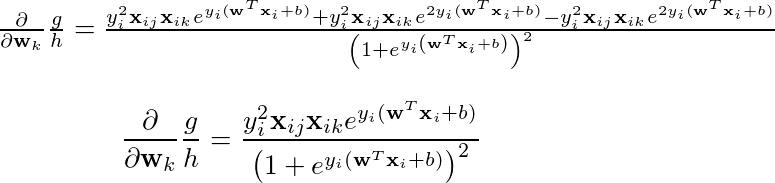

Hence,

(c) From these results, show that $L(w)$ is a convex function.

Function   is convex because its Hessian   is PSD. 

  can be shown to satisfy the criteria   because the output of all functions in the Hessian is always positive.

## **1. Feature, Classes and Linear Regression**

(a) Plot the training data in a scatter plot.

% Clean up
clc
clear
close all

disp('1. Features, Classes, and Linear Regression');

1. Features, Classes, and Linear Regression



% (a) Plot the training data in a scatter plot.

% Load training dataset
% replace \ to load file on windows
mTrain = load('data/mTrainData.txt');

% Separate features
Xtr = mTrain(: ,1); % X = single feature
Ytr = mTrain(: ,2); % Y = target value
whos

  Name          Size            Bytes  Class     Attributes

  Xtr         140x1              1120  double              
  Ytr         140x1              1120  double              
  mTrain      140x2              2240  double              



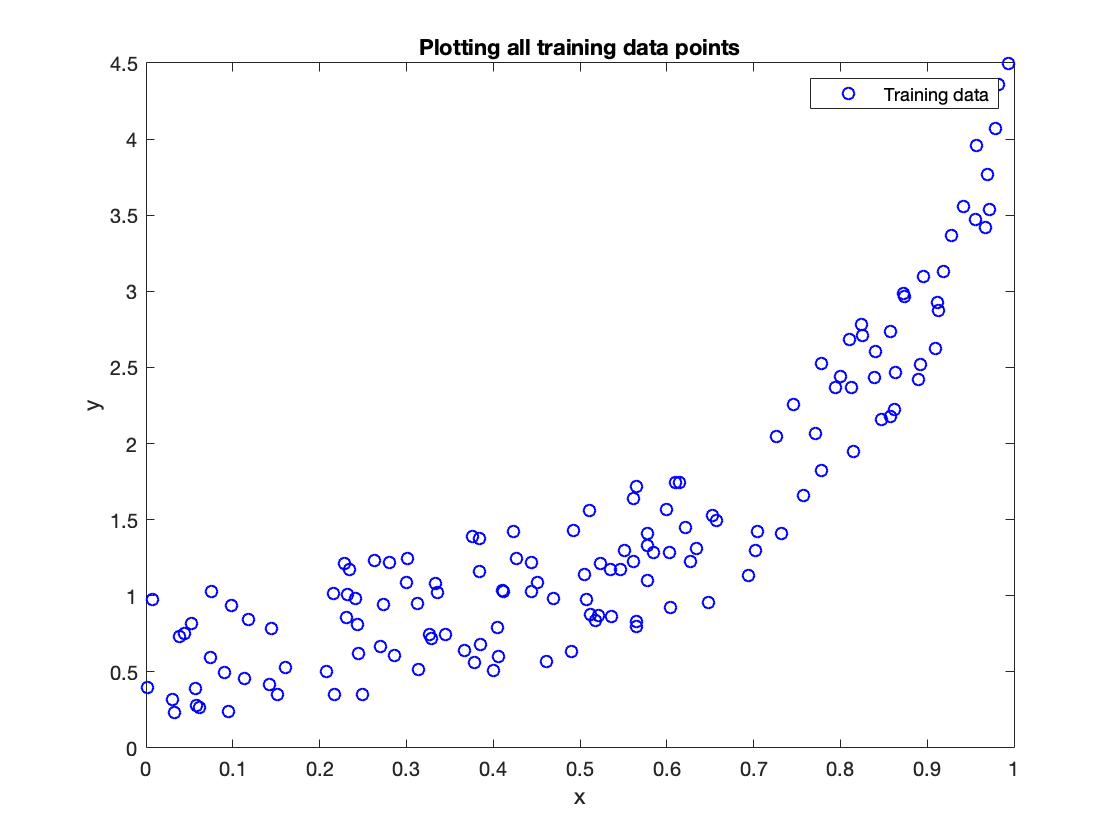


% Plot training data
figure('name', 'Training Data');
plot (Xtr, Ytr, 'bo'); 
xlabel('x');
ylabel('y');
title('Plotting all training data points');
legend('Training data');

(b) Create a linear regression learner using the above functions. Plot it on the same plot as the training data.

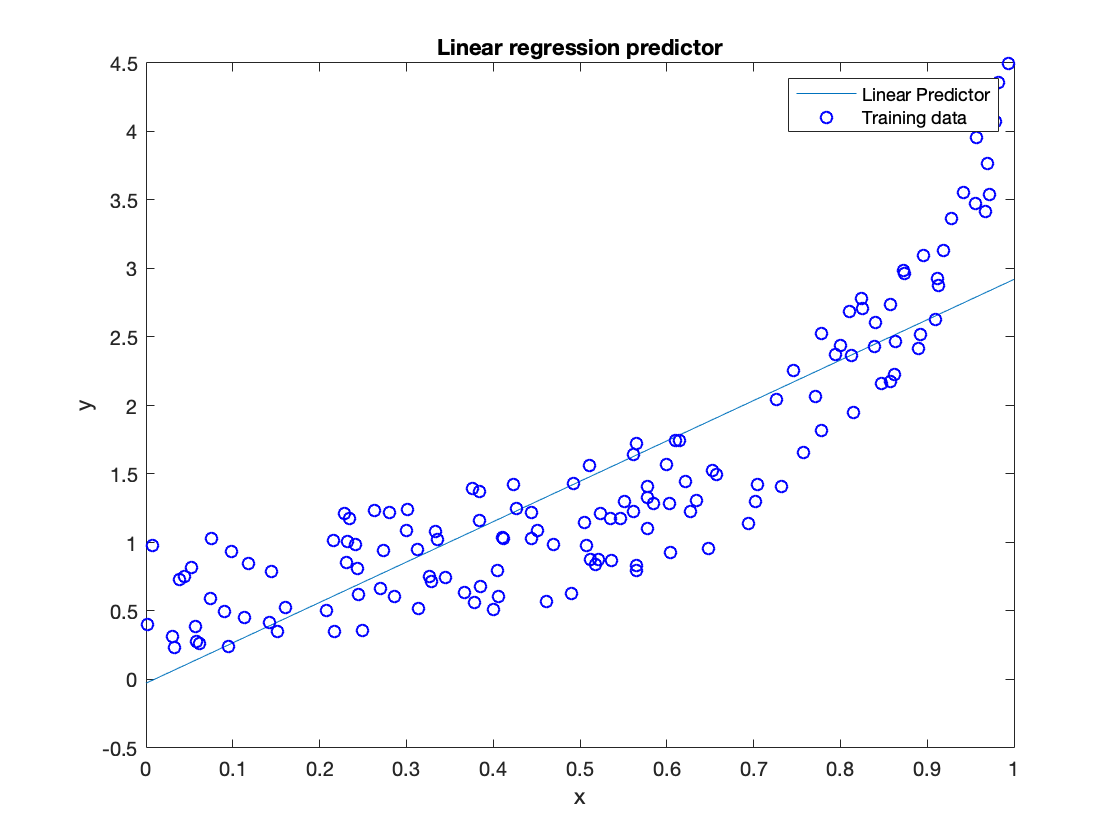

linXtr = polyx(Xtr, 1);
learner_linear = linearReg(linXtr, Ytr);
xline = [0:.01:1]'; % Transpose
yline = predict(learner_linear, polyx(xline, 1));

figure('name', 'Linear regression predictor');
plot(xline, yline);
hold on % Plot training data and label figure.
plot (Xtr, Ytr, 'bo');
legend('Linear Predictor','Training data');
xlabel('x');
ylabel('y');
title('Linear regression predictor');

(c) Create plots with the data and a higher-order polynomial (3, 5, 7, 9, 11, 13).

Quadric:

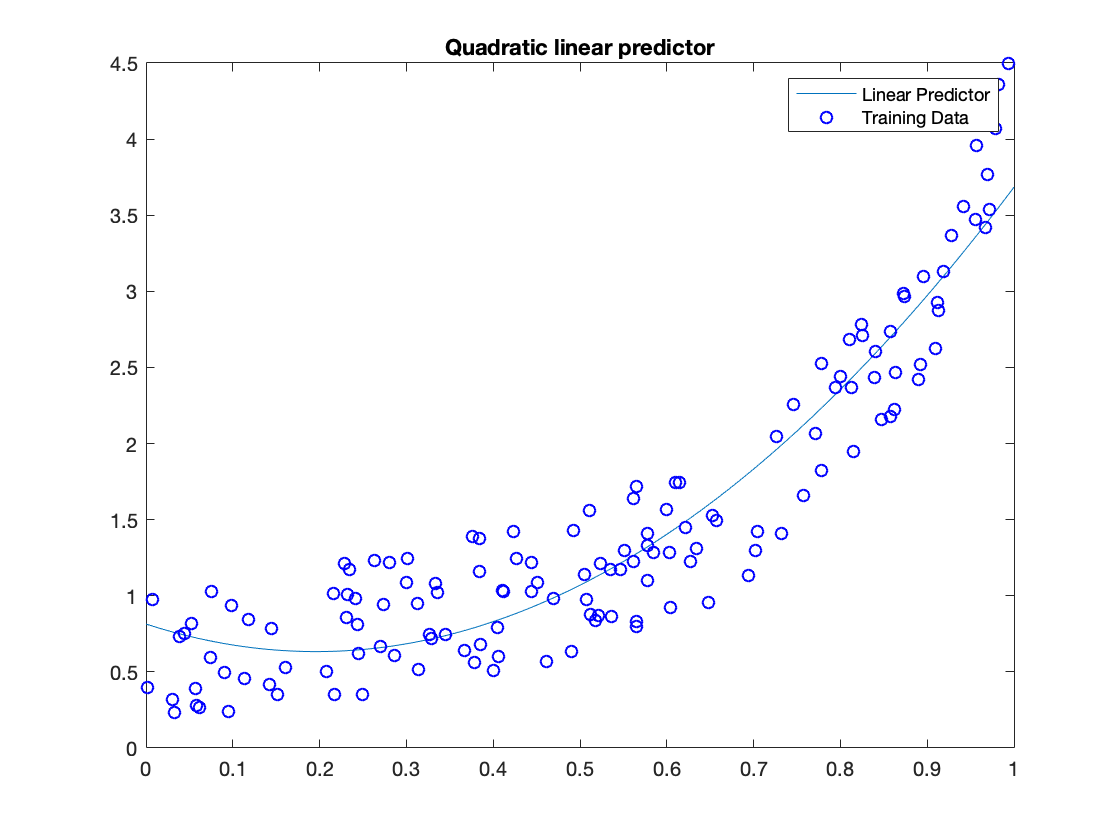

quadXtr = polyx(Xtr, 2);
learner_quadratic = linearReg(quadXtr, Ytr); % Create and learn a regression predictor from the data Xtr, ytr.
xline = [0:.01:1]' ; % Transpose
yline = predict(learner_quadratic, polyx(xline, 2)); % Assuming quadratic features
figure('name', 'Quadratic linear predictor');
plot(xline, yline);
hold on % Plot training data and label figure.
plot (Xtr, Ytr, 'bo');
legend('Linear Predictor', 'Training Data');
title('Quadratic linear predictor');

Quintic:

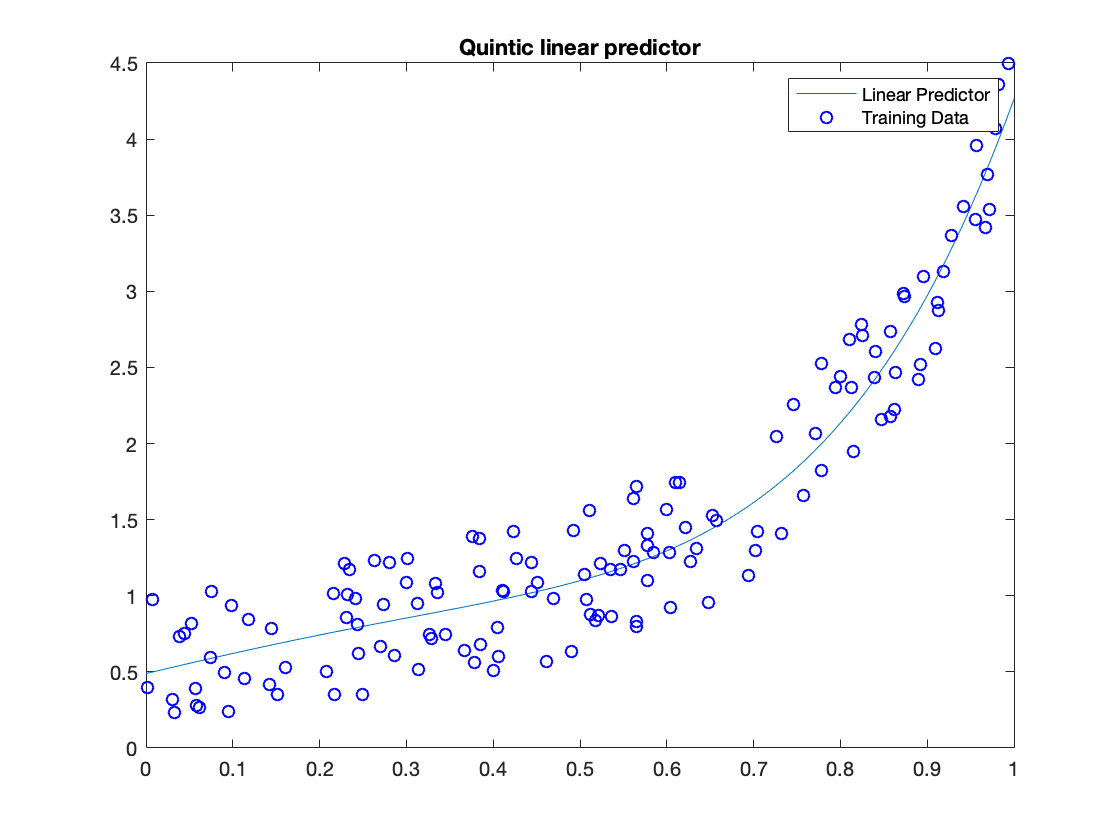

quinXtr = polyx(Xtr, 5);
learner_quintic = linearReg (quinXtr , Ytr);
yline = predict (learner_quintic , polyx(xline ,5)); % assuming quintic features
figure('name', 'Quintic linear predictor');
plot ( xline , yline );
hold on
plot (Xtr, Ytr, 'bo');
legend('Linear Predictor', 'Training Data');
title('Quintic linear predictor');

(d) Calculate the mean squared error associated with each of your learned models on the training data.

% Linear
yhat = predict(learner_linear, linXtr);
mseLinTrain = immse(yhat, Ytr);
fprintf(['The MSE for the linear predictor on' ...

The MSE for the linear predictor on training data was: 0.2366


    ' training data was: %.4f\n'], mseLinTrain);

% Quadratic
yhat = predict(learner_quadratic, quadXtr);
mseQuadTrain = immse(yhat, Ytr);
fprintf(['The MSE for the quadratic linear predictor on ' ...

The MSE for the quadratic linear predictor on training data was: 0.1092


    'training data was: %.4f\n'], mseQuadTrain);

% Quintic
yhat = predict(learner_quintic, quinXtr);
mseQinTrain = immse(yhat, Ytr);
fprintf(['The MSE for the quintic linear predictor on ' ...

The MSE for the quintic linear predictor on training data was: 0.0813


    'training data was: %.4f\n'], mseQinTrain);

(e,f,g) Calculate the MSE for each model on the test data (in mTestData.txt). Compare the obtained MAE values with the MSE values obtained above.

mTest = load('data/mTestData.txt');
xtest = mTest(: ,1); ytest = mTest(: ,2);
% Linear
Xtest = polyx(xtest, 1);
yhat = predict(learner_linear, Xtest);
mseLinTest = immse(yhat, ytest);
fprintf(['The MSE for the linear predictor on ' ...

The MSE for the linear predictor on test data was: 0.2353


    'test data was: %.4f\n'], mseLinTest);
% Quadratic
Xtest = polyx(xtest, 2);
yhat = predict(learner_quadratic, Xtest);
mseQuadTest = immse(yhat, ytest);
fprintf(['The MSE for the quadratic linear predictor on ' ...

The MSE for the quadratic linear predictor on test data was: 0.0972


    'test data was: %.4f\n'], mseQuadTest);
% Quintic
Xtest = polyx(xtest, 5);
yhat = predict(learner_quintic, Xtest);
mseQuinTest = immse(yhat, ytest);
fprintf(['The MSE for the quintic linear predictor on ' ...

The MSE for the quintic linear predictor on test data was: 0.0959


    'test data was: %.4f\n'], mseQuinTest);

Compare: Above value show that MSE for each model on test data is not varied with the MSE on Train Data.

## 2. kNN Regression